# Projeto de control B-Turtle

Definindo função de transferência encontrada utilizando identificação de sistemas.

tf33

tf33 =
  From input "u1" to output "y1":
  4.226 s^3 + 57.78 s^2 - 39.88 s - 0.02718
  -----------------------------------------
   s^3 + 0.9768 s^2 + 0.09782 s + 3.59e-13
 
Name: tf33
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 3
   Number of free coefficients: 7
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "datae". 
Fit to estimation data: 64.47% (stability enforced)
FPE: 3.562, MSE: 3.56                              
 
Model Properties



$$\frac{\theta \left(s\right)}{V\left(s\right)}=\frac{4\ldotp 336s^3 +57\ldotp 78s^2 -39\ldotp 88s-0\ldotp 02718}{s^3 +0\ldotp 9768s^2 +0\ldotp 0982s+3\ldotp 59\ldotp {10}^{-13} }$$


s = tf('s');
G_s = (4.226*s^3 + 57.78*s^2 - 39.88*s - 0.02718)/(s^3 + 0.9768*s^2 + 0.09782*s + 3.59e-13);
G_c = 30*(1/(s - 0.656))%10/(s - 0.656) + (s + 0.001)/(s + 0.864);

G_c =
 
     30
  ---------
  s - 0.656
 
Continuous-time transfer function.
Model Properties


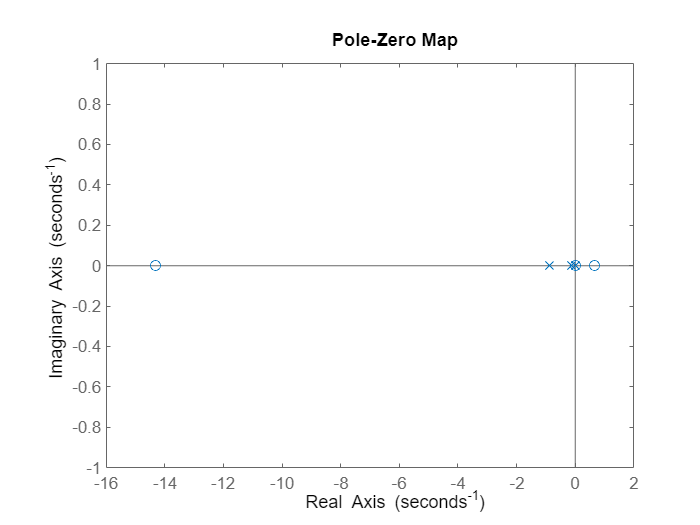

pzmap(G_s)

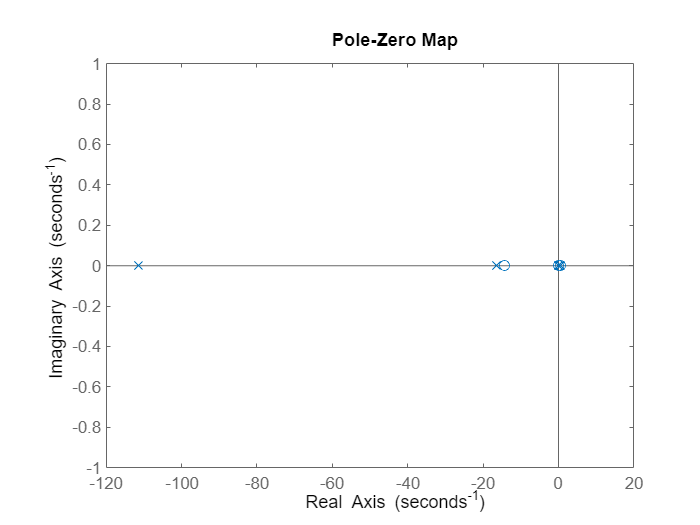

pzmap(feedback(G_s*G_c,1))

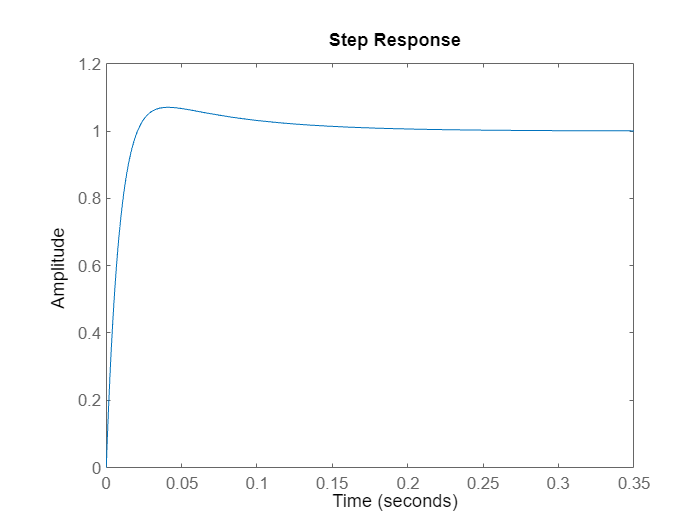

step(feedback(G_s*G_c,1))